# Testing the Data

## Linear Regression

The function `glmfit` stands for generalised linear model fit and can be used for linear regression and log regression as well as a few more (binomial etc).

For linear regression `regress` is also a good place to start.

% normalize to zero mean, unit variance


ans = 0.9540

Compare to `glmfit` to get a slope and intercept

linear_coeff =     8.6732
    1.0535


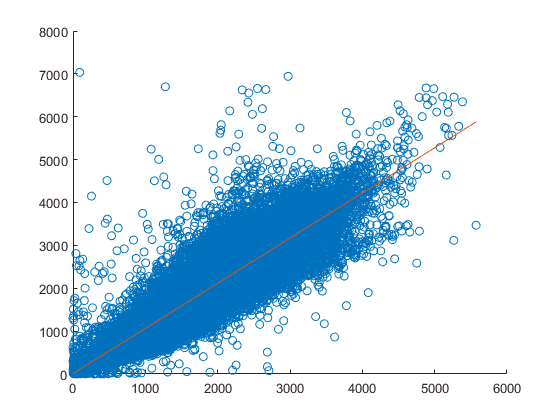

You can also access test statistics:

linear_coeff =     8.6732
    1.0535


stats = struct with fields:
         beta: [2×1 double]
          dfe: 47948
         sfit: 365.8275
            s: 365.8275
      estdisp: 1
         covb: [2×2 double]
           se: [2×1 double]
    coeffcorr: [2×2 double]
            t: [2×1 double]
            p: [2×1 double]
        resid: [47950×1 double]
       residp: [47950×1 double]
       residd: [47950×1 double]
       resida: [47950×1 double]
          wts: [47950×1 double]


ans =     2.2884
    0.0015


## Challenge

%% CHALLENGE 1
% Get regress to output upper and lower bounds 
% on the estimate
% ie [coeff,bounds] = regress()

%% CHALLENGE 2
% Use glmfit to output confidence limits and 
% plot them as dashed lines on your plot
% HINT: use the standard error (se) in the output
% statistics of glmfit

% What other stats can you get from glmfit?

There is also a function (I think it is for people who like Stata) that will print statistics into the command window

ans = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    8.6732         2.2884      3.79    0.00015081
    x1             1.0535      0.0015121    696.72             0


Number of observations: 47950, Error degrees of freedom: 47948
Root Mean Squared Error: 366
R-squared: 0.91,  Adjusted R-Squared 0.91
F-statistic vs. constant model: 4.85e+05, p-value = 0

## Logistic regression

We can also use `glmfit` for logistic regression, using the options 'binomial' and 'logit'. For an example, let's look at separating two Gaussian distributions.

% use randn to make two fake distributions


Now we need to treat them as one variable, and create a model that predicts class 1 (x1) or class 2 (x2).

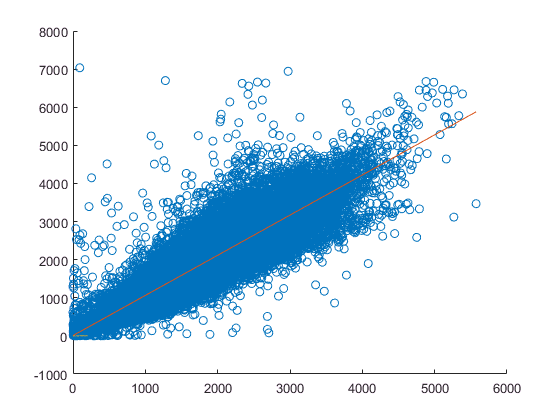

% this is our input


% this is our class label
% 0 = class 1
% 1 = class 2
% fit a logistic regresion model


log_model =    -1.9248
    1.4774


The model contains an intercept, and weights for the input (only one dimension in our case - ) and is given by:

log_model =    -1.9248
    1.4774


So to get the output of our model

% apply our weights


input =    -0.0368
   -1.2749
   -1.5796
   -1.2584
   -1.4932
   -0.4034
   -0.7512
   -0.7192
   -1.4527
    0.1285


% run the model


output =     0.4908
    0.2184
    0.1709
    0.2213
    0.1834
    0.4005
    0.3206
    0.3276
    0.1896
    0.5321


The output is between 0 and 1. It is usual to classify the input as class 1 (or Y = 0) for output < 0.5 and class 2 (or Y = 1) for output > 0.5.

Let's plot the results. We'll make class 2 red, and class 1 blue. We'll make the true predictions circles and the false ones crosses.

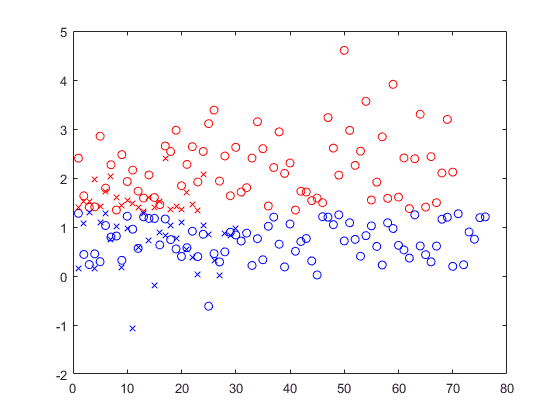

% these are correctly predicted values for class 2
% we'll make class red 

% these are the correctly predicted values for class 1


% now the incorrect predictions for 
% class 2 and class 1


We can also count how many we got right and wrong

% wrong


Nwrong = 54

Nright = 146

*Challenge*

%% CHALLENGE
% Using logistic regression to distinguish between
% two Gaussians with different means 
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Use 80% of your data from Flinders street 
% station between 8am - 9am to fit a logistic
% regression model

% Run your model on the remaining 20% of the data
% and classify it as either a weekend or weeday

%% EXTENSION
% how accurate is your classifier?

%% EXTENSION
% make your accuracy measure more robust using
% k-fold cross validation
% That means running your entire code (fit model,
% run model, test performance) in a loop. 
% For each loop use a different partition of data
% to train and test. With 10 loops, train on 
% 90% of the data, and test on 10%.
% With 5 loops, train on 80% of the data and 
% test on 20%.

## Testing Gaussians

Many standard tests are built into MATLAB. For example, to test if data are normally distributed we can use `kstest`.

Another common test is `ttest2` (two-sampled t-test) and its non-parametric cousin `ranksum` (Wilcoxon rank sum / Mann-Whitney U test - why do statisticians like to name everything after themselves?).

*Challenge*

`%% CHALLENGE`

`%Check if the weekday pedestrian count data from`

`%Southern Cross station and Flinders Street`

`%station is normally distributed.`

`%% CHALLENGE`

`%Check if there is any difference between the two`

`%distributions? Use ttest2 if the data are normal,`

`%or ranksum if they are not.`